%% ============================================
%  PARAMETERS
%% ============================================
J1 = 5e-5;  B1 = 1e-2;  r1 = 2e-2;  Kt = 3e-2;
K  = 2e4;   B  = 20;    r2 = 2e-2;
J2 = 2e-5;  B2 = 2e-2;

%% ============================================
%  BUILD TRANSFER FUNCTION
%% ============================================
num_poly = Kt * r1 * [J2, (B2 + r2^2*B), r2^2*K];
term3 = J1*J2;
term2 = J1*B2 + B1*J2 + r2^2*J1*B + r1^2*J2*B;
term1 = B1*B2 + r2^2*B1*B + r1^2*B2*B + r1^2*J2*K + r2^2*J1*K;
term0 = r1^2*B2*K + r2^2*B1*K;
den_poly  = [term3, term2, term1, term0, 0];
sys_pos   = tf(num_poly, den_poly);
s         = tf('s');
sys_speed = minreal(s * sys_pos);
disp('Transfer Function:'); sys_speed

Transfer Function:

sys_speed =
 
      12 s + 4800
  --------------------
  s^2 + 760 s + 2.4e05
 
Continuous-time transfer function.



%% ============================================
%  DEFINE INPUTS
%% ============================================
t      = (0:0.0001:0.05)';
nx     = 2;
u_step = [zeros(nx,1); ones(length(t)-nx, 1)];
u_sine1 = sin(10   * t);
u_sine2 = sin(489  * t);
u_sine3 = sin(5000 * t);

%% ============================================
%  SIMULATE OUTPUTS
%% ============================================
y_step  = lsim(sys_speed, u_step,  t);
y_sine1 = lsim(sys_speed, u_sine1, t);
y_sine2 = lsim(sys_speed, u_sine2, t);
y_sine3 = lsim(sys_speed, u_sine3, t);

%% ============================================
%  IDENTIFY APPROXIMATED MODEL
%% ============================================
Ts     = t(2) - t(1);
data   = iddata(y_step, u_step, Ts);
sys_id = tfest(data, 2);


disp('=== Approximated Model ==='); sys_id

=== Approximated Model ===

sys_id =
 
  From input "u1" to output "y1":
      12 s + 4800
  --------------------
  s^2 + 760 s + 2.4e05
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 1
   Number of free coefficients: 4
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 100%                     
FPE: 9.263e-29, MSE: 9.044e-29                   
 
Model Properties


disp('=== Theoretical Model ===');  sys_speed

=== Theoretical Model ===

sys_speed =
 
      12 s + 4800
  --------------------
  s^2 + 760 s + 2.4e05
 
Continuous-time transfer function.


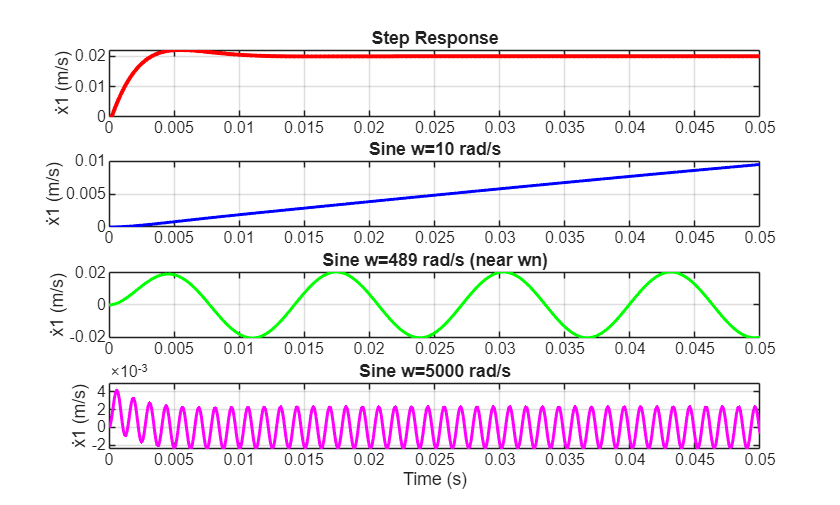


%% ============================================
%  PLOT ALL RESPONSES
%% ============================================
figure('Color','w');
subplot(4,1,1);
plot(t, y_step,  'r', 'LineWidth', 2);
title('Step Response');
ylabel('ẋ1 (m/s)'); grid on;

subplot(4,1,2);
plot(t, y_sine1, 'b', 'LineWidth', 1.5);
title('Sine w=10 rad/s');
ylabel('ẋ1 (m/s)'); grid on;

subplot(4,1,3);
plot(t, y_sine2, 'g', 'LineWidth', 1.5);
title('Sine w=489 rad/s (near wn)');
ylabel('ẋ1 (m/s)'); grid on;

subplot(4,1,4);
plot(t, y_sine3, 'm', 'LineWidth', 1.5);
title('Sine w=5000 rad/s');
xlabel('Time (s)'); ylabel('ẋ1 (m/s)'); grid on;

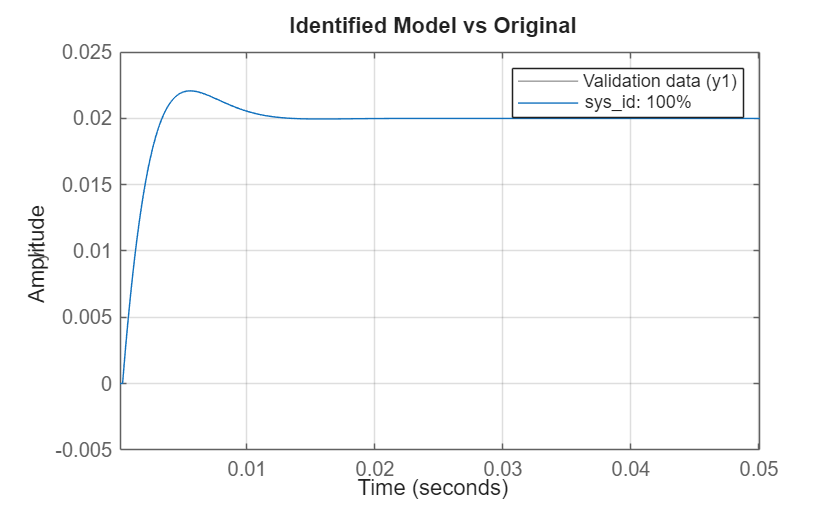


%% ============================================
%  COMPARE IDENTIFIED VS ORIGINAL
%% ============================================
figure('Color','w');
compare(data, sys_id);
title('Identified Model vs Original');
grid on;

%% ============================================
%  PART 3: Evaluate Goodness of Approximation
%% ============================================

% --- Simulate sys_id with same inputs ---
y_id_step  = lsim(sys_id, u_step,  t);
y_id_sine1 = lsim(sys_id, u_sine1, t);
y_id_sine2 = lsim(sys_id, u_sine2, t);
y_id_sine3 = lsim(sys_id, u_sine3, t);

% --- Fit percentage for each input ---
fit_step  = 100*(1 - norm(y_step  - y_id_step) /norm(y_step  - mean(y_step)));
fit_sine1 = 100*(1 - norm(y_sine1 - y_id_sine1)/norm(y_sine1 - mean(y_sine1)));
fit_sine2 = 100*(1 - norm(y_sine2 - y_id_sine2)/norm(y_sine2 - mean(y_sine2)));
fit_sine3 = 100*(1 - norm(y_sine3 - y_id_sine3)/norm(y_sine3 - mean(y_sine3)));

fprintf('\n========================================\n');

fprintf('   GOODNESS OF APPROXIMATION\n');

   GOODNESS OF APPROXIMATION


fprintf('========================================\n');

fprintf('Fit Step input:         %.2f%%\n', fit_step);

Fit Step input:         100.00%


fprintf('Fit Sine w=10:          %.2f%%\n', fit_sine1);

Fit Sine w=10:          100.00%


fprintf('Fit Sine w=489:         %.2f%%\n', fit_sine2);

Fit Sine w=489:         100.00%


fprintf('Fit Sine w=5000:        %.2f%%\n', fit_sine3);

Fit Sine w=5000:        100.00%


fprintf('========================================\n');

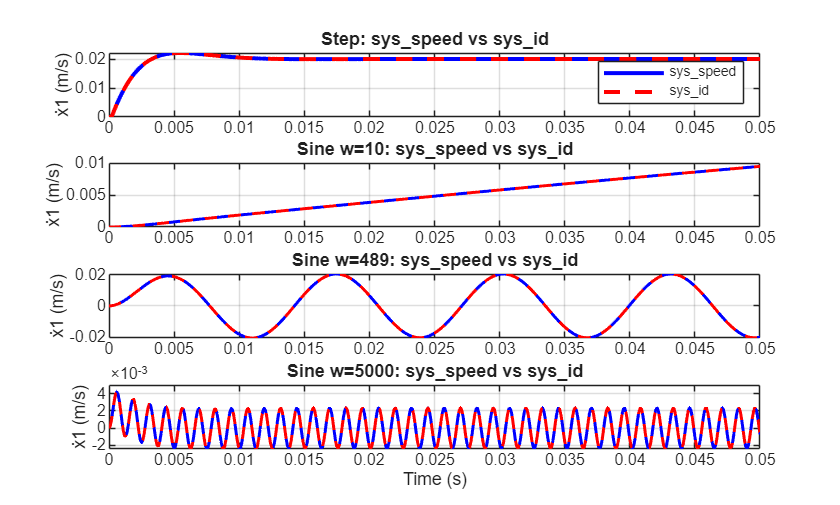


% --- Plot: sys_speed vs sys_id for all inputs ---
figure('Color','w');
subplot(4,1,1);
plot(t, y_step,     'b',  'LineWidth', 2); hold on;
plot(t, y_id_step,  'r--','LineWidth', 2);
title('Step: sys\_speed vs sys\_id');
ylabel('ẋ1 (m/s)');
legend('sys\_speed','sys\_id'); grid on;

subplot(4,1,2);
plot(t, y_sine1,    'b',  'LineWidth', 1.5); hold on;
plot(t, y_id_sine1, 'r--','LineWidth', 1.5);
title('Sine w=10: sys\_speed vs sys\_id');
ylabel('ẋ1 (m/s)'); grid on;

subplot(4,1,3);
plot(t, y_sine2,    'b',  'LineWidth', 1.5); hold on;
plot(t, y_id_sine2, 'r--','LineWidth', 1.5);
title('Sine w=489: sys\_speed vs sys\_id');
ylabel('ẋ1 (m/s)'); grid on;

subplot(4,1,4);
plot(t, y_sine3,    'b',  'LineWidth', 1.5); hold on;
plot(t, y_id_sine3, 'r--','LineWidth', 1.5);
title('Sine w=5000: sys\_speed vs sys\_id');
xlabel('Time (s)'); ylabel('ẋ1 (m/s)'); grid on;

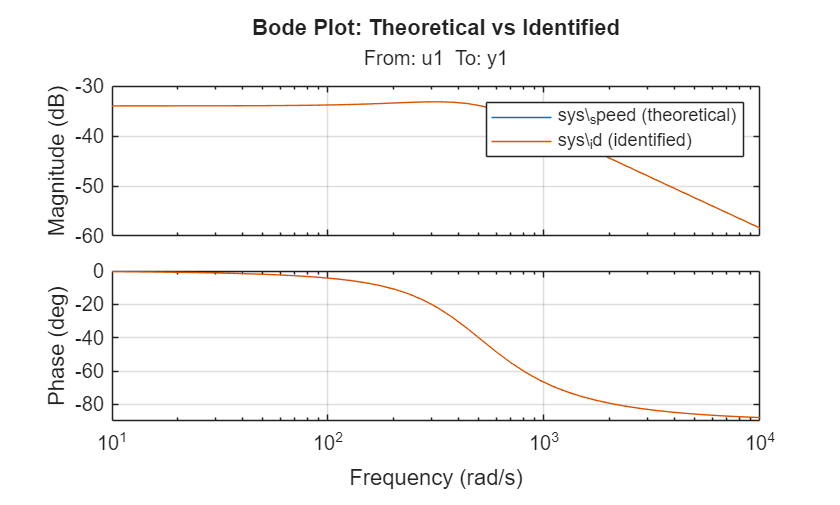


% --- Bode comparison ---
figure('Color','w');
bode(sys_speed, sys_id);
legend('sys\_speed (theoretical)','sys\_id (identified)');
title('Bode Plot: Theoretical vs Identified');
grid on;